## Parameters

on_GPU = false;
T = 40; % sec
N = 200; % number of neurons 200
input_Hz = 50; % Hz
conn_prob_input2E = 0.1; % a.u.
conn_strength_input2E = 1; % a.u.
conn_prob_E2E = 0.25; % a.u.
conn_strength_E2E = 1; % a.u.
STDP_learning_rate_E2E = 1; % a.u. (STDP)

plasticity_type = "rbSTDP";

plot_synapses = false;
plot_Vm = false;
plot_spikes = false;
plot_refractoriness = false;
plot_weights = true;
plot_Hz = true;
plot_stimulation = true;
plot_STDP_traces = false;
plot_resource_pool = true;
plot_digraph = true;

## Run a single EI pool with

samples = 16;
pool_single = cell(samples);

parfor n=1:samples
    % Set up
    tic
    pool_single{n} = RB_STDP_EI_pool( ...
        T, ...
        N, ...
        on_GPU, ...
        conn_prob_input2E, ...
        conn_strength_input2E, ...
        conn_prob_E2E, ...
        conn_strength_E2E, ...
        plasticity_type, ...
        plot_synapses, ...
        plot_Vm, ...
        plot_spikes, ...
        plot_refractoriness, ...
        plot_weights, ...
        plot_Hz, ...
        plot_stimulation, ...
        plot_STDP_traces, ...
        plot_resource_pool, ...
        plot_digraph ...
        );
    pool_single{n}.set_input( ...
        input_Hz ...
        );
    toc
    % Runa
    tStart = tic;
    pool_single{n}.run( ...
        false, ... % plot_during
        STDP_learning_rate_E2E ...
        );
    tEnd = toc(tStart);
    fprintf( ...
        'Elapsed time is %d minutes and %f seconds\n', ...
        floor(tEnd/60), ...
        rem(tEnd,60) ...
        );
    % Finish
    tic
    pool_single{n}.finish()
    toc
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 16 workers.
Elapsed time is 1.022025 seconds.
Elapsed time is 1.072097 seconds.
Elapsed time is 1.041071 seconds.
Elapsed time is 1.044975 seconds.
Elapsed time is 1.060451 seconds.
Elapsed time is 1.010423 seconds.
Elapsed time is 0.973652 seconds.
Elapsed time is 1.082744 seconds.
Elapsed time is 1.041219 seconds.
Elapsed time is 1.039418 seconds.
Elapsed time is 1.048114 seconds.
Elapsed time is 1.060351 seconds.
Elapsed time is 1.032429 seconds.
Elapsed time is 1.117202 seconds.
Elapsed time is 1.109003 seconds.
Elapsed time is 1.112109 seconds.
Elapsed time is 70 minutes and 37.750382 seconds
Elapsed time is 0.027754 seconds.
Elapsed time is 71 minutes and 58.059697 seconds
Elapsed time is 0.021716 seconds.
Elapsed time is 77 minutes and 46.655327 seconds
Elapsed time is 0.029025 seconds.
Elapsed time is 79 minutes and 27.997102 seconds
Elapsed time is 0.027308 seconds.
Elapsed time 

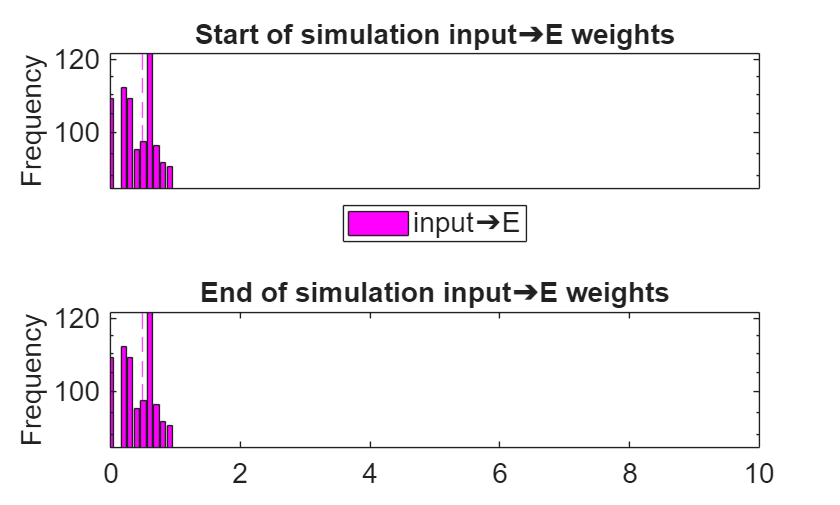

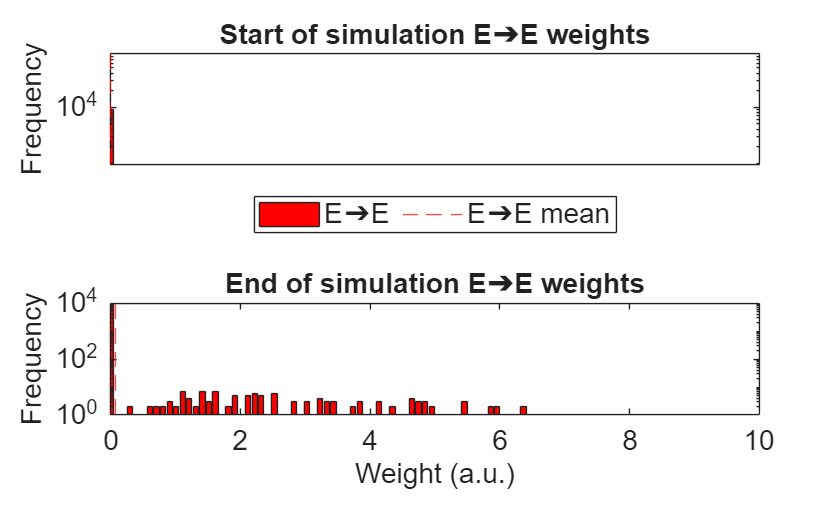

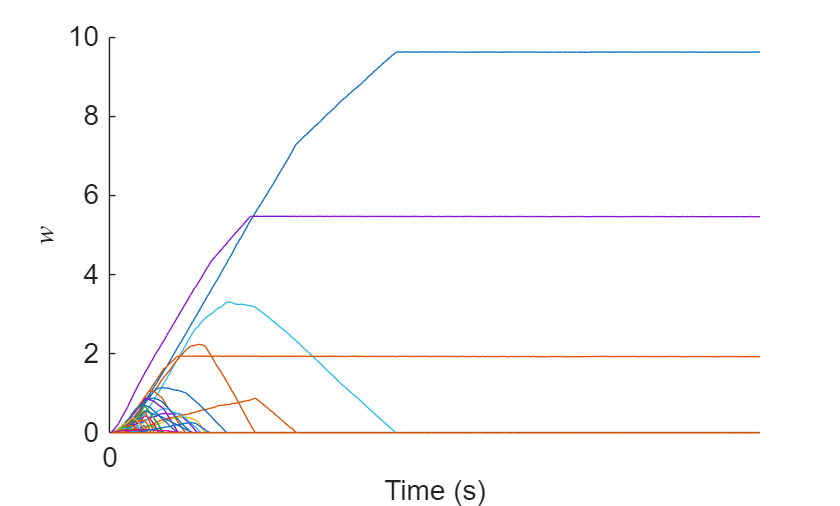

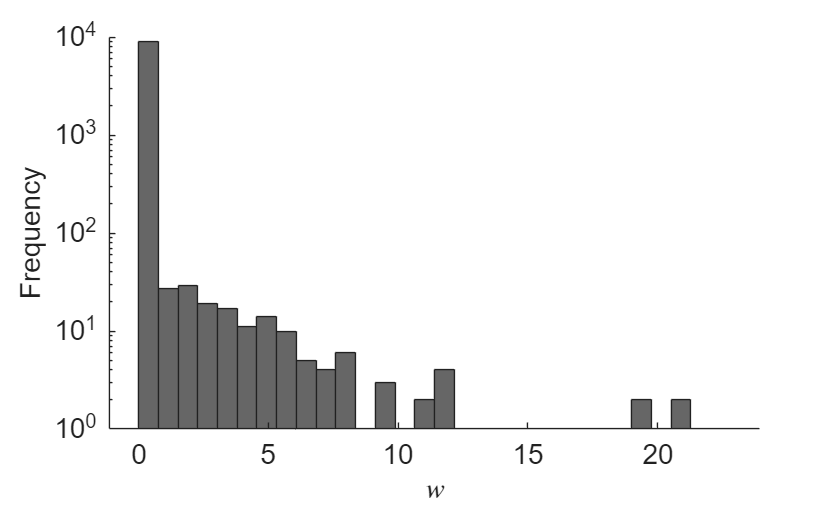

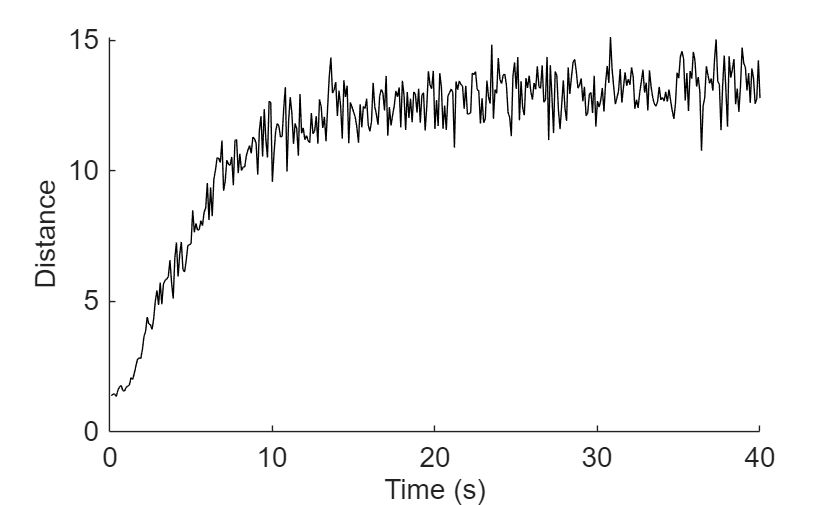

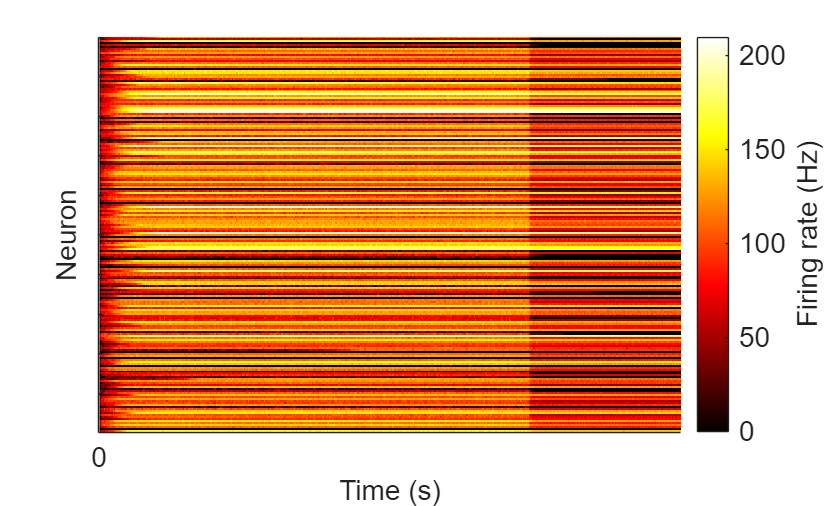

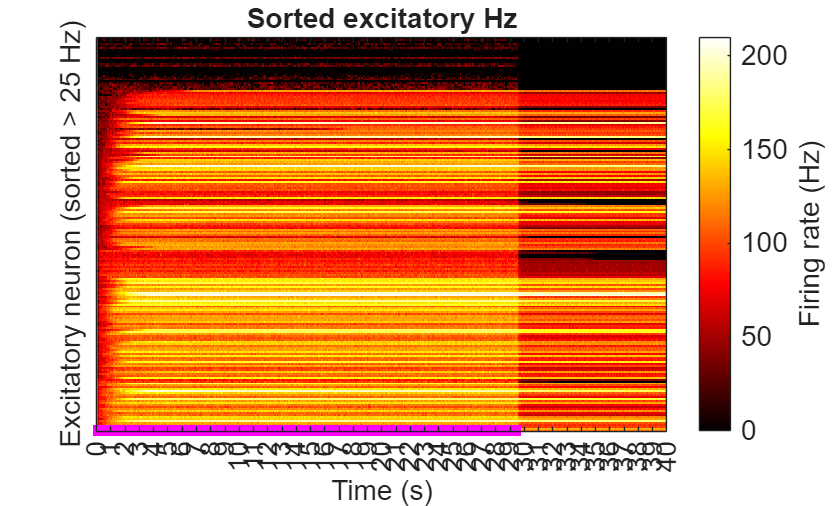

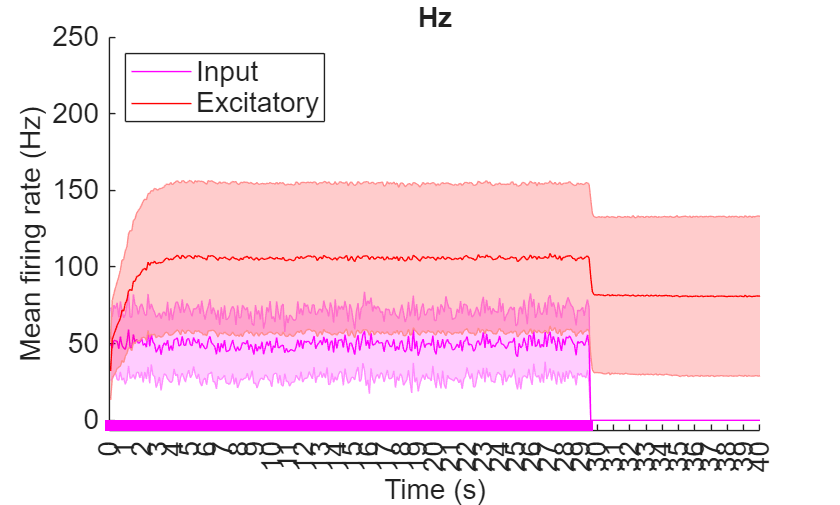

% Plot
tic
pool_single{12}.plot( ... % 3 6 7 8 12
    true ... % export
    )

toc

Elapsed time is 68.388970 seconds.
